# Method#1 Random End Point

## 隨機端點法

畫出單位圓和內接正三角形

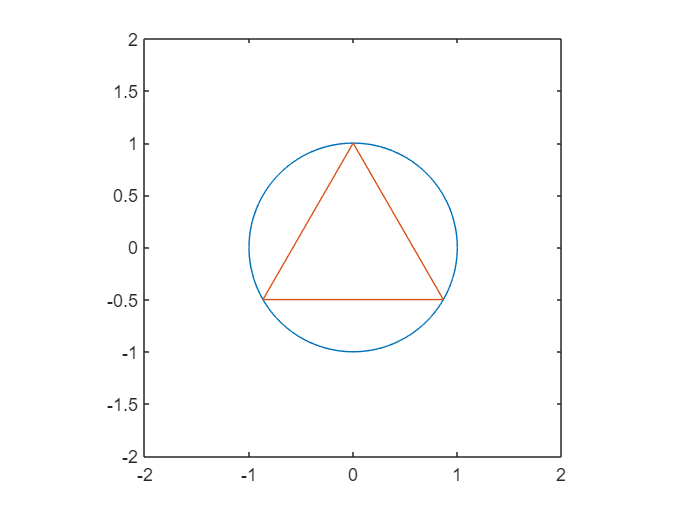

r = 1;
syms x y
fimplicit(x^2+y^2 == r^2, [-2 2, -2 2])
axis equal;
hold on
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
plot(t(:,1),t(:,2))
hold off

## Probability

$N$：樣本數

$P$：機率

$a=\sqrt 3
$：正三角形邊長

$chord\_len$：算出來的弦長

### 顏色

圓形：藍色

內接三角形：橘色

圓上的點：紅色(實心)

- 變成 rand(1) * 2pi

- 有超過：綠色

- 沒超過：紅色

- 算機率跟畫圖分成兩個Block

- 先畫圖再用機率

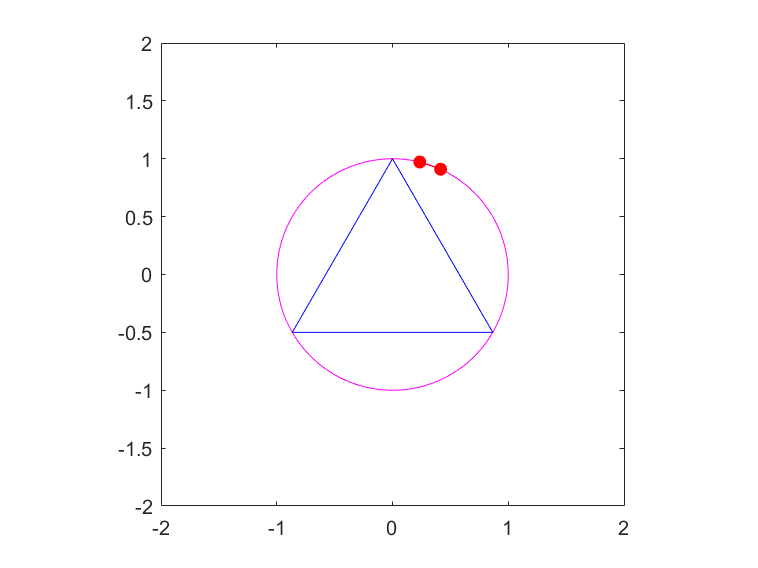

N = 100;
M = 10; %樣本數
count = 0;  %超過根號3的次數
theta = linspace(0, 2*pi, N);
for i = 1:M
    theta1 = theta(randi(N));
    theta2 = theta(randi(N));
    p1 = [cos(theta1) sin(theta1)]; % 點一
    p2 = [cos(theta2) sin(theta2)]; % 點二
    len = sqrt((p1(1)-p2(1))^2 + ((p1(2)-p2(2))^2));
    
    % Plot
    fimplicit(x^2+y^2 == r^2, [-2 2, -2 2], 'm')
    hold on
    plot(t(:,1),t(:,2),'b-');

    plot(p1(1), p1(2),'ro-', 'MarkerFaceColor', 'r')
    plot(p2(1), p2(2),'ro-', 'MarkerFaceColor', 'r')
    if len >= sqrt(3)
        line([p1(1); p2(1)], [p1(2); p2(2)], 'color', 'b') %超過畫藍線
        count = count + 1;
    else
        line([p1(1); p2(1)], [p1(2); p2(2)], 'color', 'r') %沒超過畫紅線
    end
    axis equal;
    hold off
    pause(0.01)
end

%機率
P = count/M

P = 0.3000